# Satélite en órbita alrededor de la Tierra

Un satélite orbitando la Tierra, la Tierra está en el origen (inicialmente). El satélite tiene una masa de 20 toneladas y se encuentra a 108 km de altura (eje x). Los vectores tienen los datos [tierra, satélite].


$$\begin{array}{l}
y=\left\lbrack \begin{array}{c}
r\\
v
\end{array}\right\rbrack \\
\mathrm{y'}=\left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack \\
\frac{\textrm{d}}{\textrm{d}t}y=f\left(t,y\right)
\end{array}$$


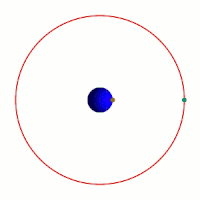

Solución para Satélite y Tierra. Tomamos como posición inicial la Tierra y el satélite solo cambia la altura a la que esta del centro de la Tierra.

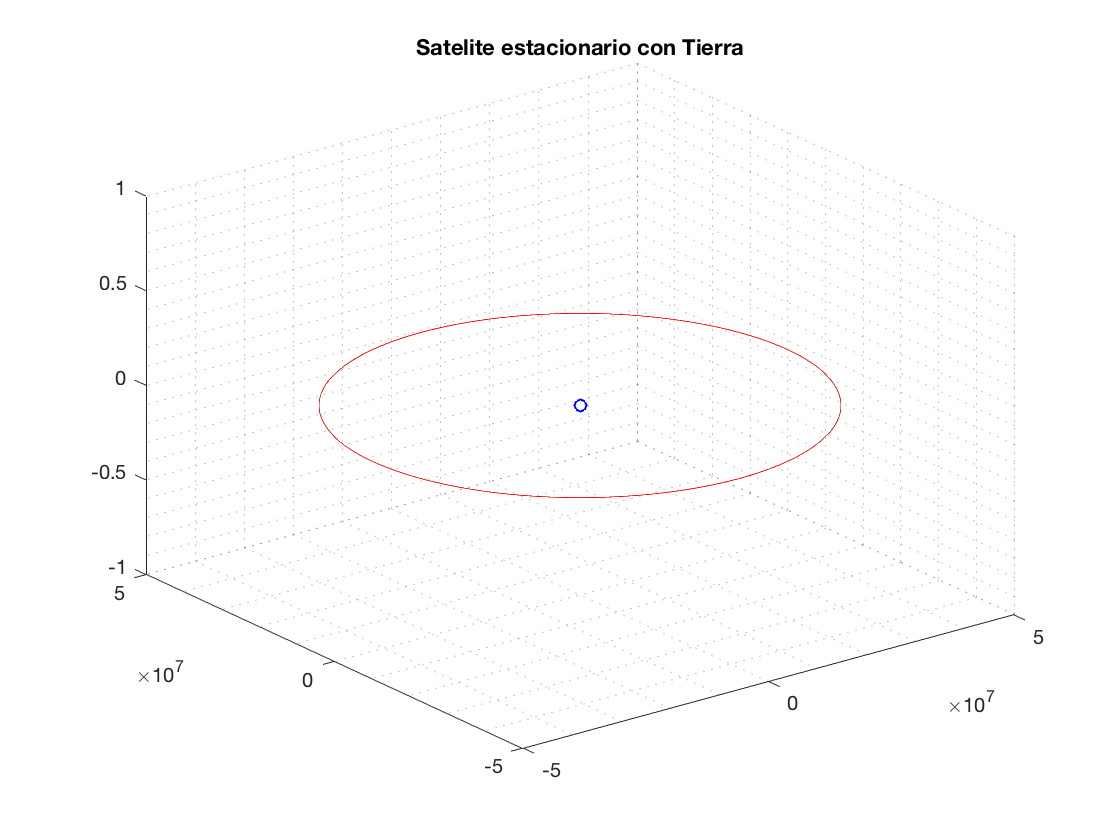

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mT = 5.9736E+24;              % masa de la Tiera
ms = 20000;                   % masa del satélite
m = [mT, ms];

rT = 6371e3;                        % radio de la Tierra m
hs = 35786000;                      % altura satélite geoestacionario m
r0 = [ [0;0;0], [rT+hs;0;0] ];      % 3x2 Posición incial de la tierra y posicion inicial del satélite
vs = sqrt(G * m(1)/r0(1,2));        % Fórmula para sacar la velocidad del satélite
v0 = [ [0;0;0], [0;vs;0] ];         % 3x2 Velocidad inicial de la Tierra y del Satélite

ws = vs/(rT+hs);                    % Velocidad del satélite entre la posición del satélite.
% Velocidad angular
T = (2*pi)/ws;                      % Periodo= Tiempo del satélite en dar una vuelta
h = 60;                             % Longitud de intervalo en segundos
nv = 4;
Nk = nv*ceil(T/h);                   % 4* 1436 = 5475

%6 dimensiones porque tengo 2 cuerpos y cada uno 3 dimensiones
pos = zeros(6,Nk+1);                % matriz de 6 filas con 5745 columnas
% las filas 1:3 son de la tierra, las 4:6 son del satélite
pos(:,1) = [r0(:,1);r0(:,2)];       % Hace que la matriz pos tenga en la primera columna los valores de r0
% en pos(4,1) = rT+hs
% las columnas van a tener los valores de x,y,z de la Tierra y del Satélite
% Aqui ya hicimos la posicion inicial

%Rk4, o usamos el ivps
y = [r0;v0];                        % Se hace una matriz de 6*2 con posicion de T y S, velocidad T, S

% Se empieza en 2 para empezar en la segunda columna de la matriz e

% ir avanzando en el tiempo
for t=2:Nk+1
    s1 = f(t,y);
    s2 = f(t+h/2,y+(h/2)*s1);
    s3 = f(t+h/2,y+(h/2)*s2);
    s4 = f(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    %   slope = s1;
    y = y + slope*h;            % Porque se hace *h ?
    
    r = y(1:3,:);                % Se crea una matriz r con los valores de la matriz y
    % del renglon 1 a 3 (posiciones), y todas las columnas (T, S)
    pos(:,t) = [r(:,1);r(:,2)];    % Cambia la columna t de la matriz pos o sea pone las posiciones en tiempo t
    % de la T, S
end
plot3(pos(1,:),pos(2,:),pos(3,:),'ob');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'r');
grid minor;
title('Satelite estacionario con Tierra')
hold off

## Explicacion del algoritmo

Utilizamos la función de Ley Gravitacional con los datos reales de la masa de la Tierra, el satelite. El radio de la Tierra, la altura del satelite a la superficie de la Tierra.

Para guardar las posiciones de la Tierra y el satelite, se crea una matriz de 3000 x 6. En la cual cada columna se representa un tiempo t. Las filas 1 a 3 corresponden a la posicion de la Tierra en x,y,z. Las filas 4 a 6 corresponden a las posiciones del satelite en x,y,z.

Solución para la relación Luna y Tierra tomando como referencia el centro de la Tierra.

global G m;
G = 6.67408E-11;             
mT = 5.9736E+24;            
mS = 7,349E+22;                

mS = 7

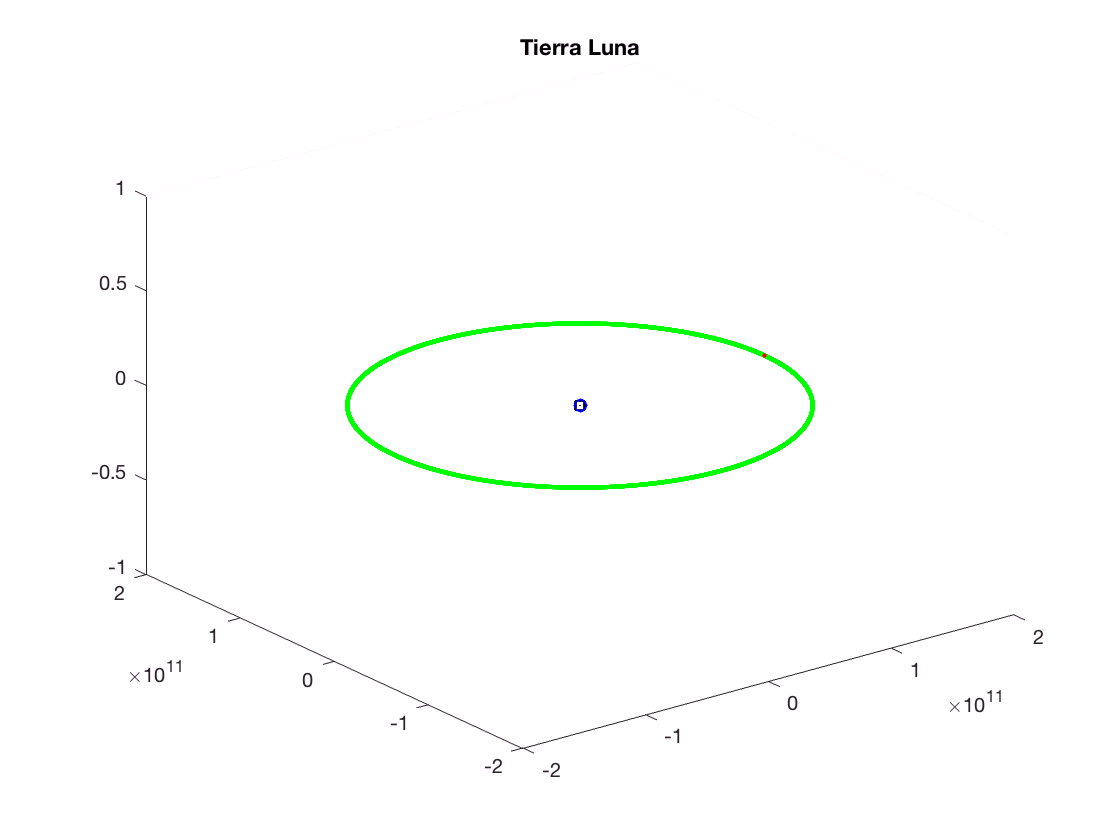

m = [mT, mS];

rT = 6371e3;                        
dTs = 384400000;                    
rS = 1737100;                        
r0 = [ [0;0;0], [rT+dTs+rS;0;0] ];    
vT = sqrt(G * m(1)/r0(1,2));       
v0 = [ [0;0;0], [0;vT;0] ];        

ws = vT/(rT+dTs);                 

T = (2*pi)/ws;                     
h = 300;                             
nv = 4;
Nk = nv*ceil(T/h);                  

pos = zeros(6,Nk+1);      

pos(:,1) = [r0(:,1);r0(:,2)];       

y = [r0;v0];

for t=2:Nk+1
    s1 = f(t,y);
    s2 = f(t+h/2,y+(h/2)*s1);
    s3 = f(t+h/2,y+(h/2)*s2);
    s4 = f(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    y = y + slope*h;            
    
    r = y(1:3,:);               

    pos(:,t) = [r(:,1);r(:,2)];    
end

plot3(pos(1,:),pos(2,:),pos(3,:),'ob');
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'k');
title('Tierra Luna');
grid minor;
hold off

## Solución de un sistema de tres variables, Venus, Tierra y el Sol. Tomando al sol como la referencia

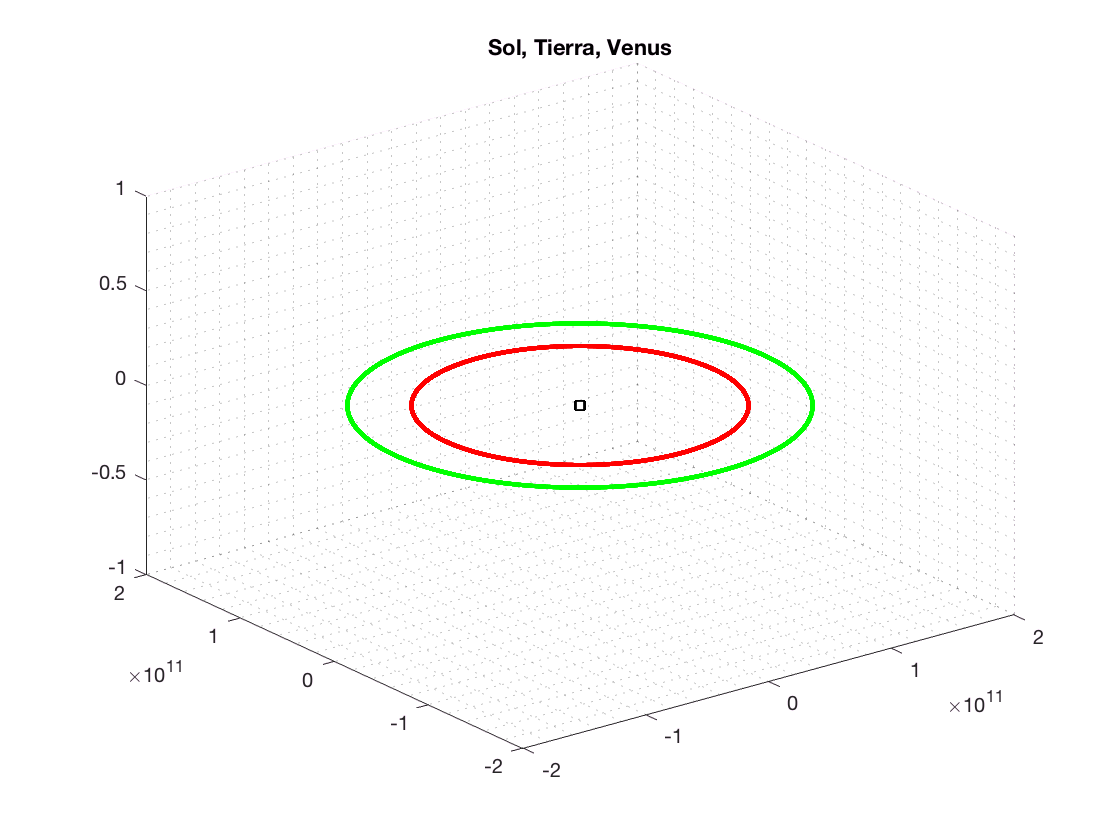

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mT = 5.9736E+24;              % masa de la Tiera
mV = 4.867E+24;               % masa de Venus
mS = 1.989E+30;               % masa del Sol
m = [mS, mT, mV];

rT = 6371e3;                        % radio de la Tierra m
rV = 6051800;                       % Radio de Venus
rS = 695510000;                     % Radio del Sol
dTS = 149600000000;                 % Distancia del sol a la tierra
dSV = 108200000000;                 % Distancia de Venus al Sol
r0 = [[0;0;0], [rS+dTS+rT;0;0],[rS+dSV+rV;0;0]];     % 3x2 Posición incial del Sol, Tierra y Venus
vT = sqrt(G * m(1)/r0(1,2));        % Fórmula para sacar la velocidad de la Tierra
vV = sqrt(G * m(1)/r0(1,3));        % Fórmula para sacar la velocidad de Venus
v0 = [ [0;0;0], [0;vT;0] , [0;vV;0]];         % 3x2 Velocidad inicial de la Tierra y de Venus

wsT = vT/(rS+dTS);                  
T = (2*pi)/wsT;                     
h = 3600;                          
nv = 4;
NktT = nv*ceil(T/h);                    

wsV = vV/(rS+dSV);

Tl = (2*pi)/wsV;
NktV = nv*ceil(Tl/h);

pos = zeros(9,NktT+1);               
pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];       

y = [r0(:,1), r0(:,2); v0(:,1),v0(:,2)];    
z = [r0(:,1), r0(:,3); v0(:,1),v0(:,3)];    

% Se empieza en 2 para empezar en la segunda columna de la matriz e

% ir avanzando en el tiempo
for t=2:NktT+1
    s1 = f(t,y);
    s2 = f(t+h/2,y+(h/2)*s1);
    s3 = f(t+h/2,y+(h/2)*s2);
    s4 = f(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    y = y + slope*h; 
    
    z1 = f(t,z);
    z2 = f(t+h/2,z+(h/2)*z1);
    z3 = f(t+h/2,z+(h/2)*z2);
    z4 = f(t+h, z+h*z3);
    zlope = (z1+2*z2+2*z3+z4)/6;          
    z = z + zlope*h;
    
    r = [y(1:3,:), z(1:3,2)];                
   
    pos(:,t) = [r(:,1);r(:,2);r(:,3)];    % Cambia la columna t de la matriz pos o sea pone las posiciones en tiempo t
    % de la T, S, V
end

plot3(pos(1,:),pos(2,:),pos(3,:),'sk');  %SOl
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'.g');     % Tierra
hold on;
plot3(pos(7,:),pos(8,:),pos(9,:),'.r');     % Venus
grid minor;
title('Sol, Tierra, Venus');
hold off

## Solución de un sistema de tres variables, Luna, Tierra y el Sol. Tomando al Sol como la referencia del centro de la Tierra y el centro de la Tierra como referencia de la Luna.

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mT = 5.9736E+24;              % masa de la Tiera
mL = 7,349E+22;               % masa de Luna

mL = 7

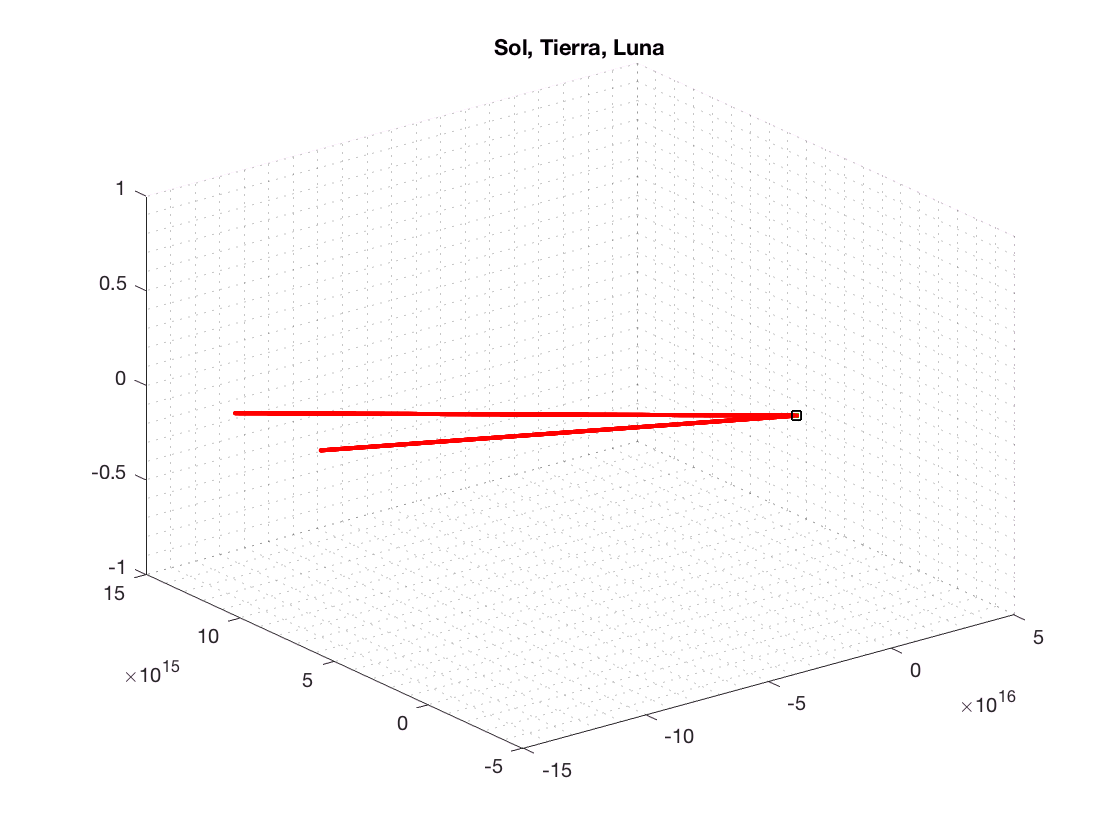

mS = 1.989E+30;               % masa del Sol
m = [mS, mT, mL];

rT = 6371e3;                        % radio de la Tierra m
rL = 1737100;                       % Radio de la Luna en m
rS = 695510000;                     % Radio del Sol
dTS = 149600000000;                 % Distancia del sol a la tierra
dTL = 384400;                       % Distancia de la Luna a la Tierra
r0 = [[0;0;0], [rS+dTS+rT;0;0], [rS+dTS+rT+rT+dTL+rL;0;0]];     % 3x2 Posición incial del Sol, Tierra y Luna
vT = sqrt(G * m(1)/r0(1,2));        % Fórmula para sacar la velocidad de la Tierra
vL = sqrt(G * m(2)/(rT+dTL+rL));        % Fórmula para sacar la velocidad de la Luna
v0 = [ [0;0;0], [0;vT;0] , [0;vL;0]];         % 3x2 Velocidad inicial de la Tierra y de la Luna

wsT = vT/(rS+dTS);                  
T = (2*pi)/wsT;                     
h = 3600;                          
nv = 4;
NktT = nv*ceil(T/h);                    

wTL = vL/(rT+dTL);

Tl = (2*pi)/wTL;
NktV = nv*ceil(Tl/h);

pos = zeros(9,NktT+1);               
pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];       

y = [r0(:,1), r0(:,2); v0(:,1),v0(:,2)];    
z = [r0(:,1), r0(:,3); v0(:,2),v0(:,3)];    

% Se empieza en 2 para empezar en la segunda columna de la matriz e

% ir avanzando en el tiempo
for t=2:NktT+1
    s1 = f(t,y);
    s2 = f(t+h/2,y+(h/2)*s1);
    s3 = f(t+h/2,y+(h/2)*s2);
    s4 = f(t+h, y+h*s3);
    slope = (s1+2*s2+2*s3+s4)/6;
    y = y + slope*h; 
    
    z1 = f(t,z);
    z2 = f(t+h/2,z+(h/2)*z1);
    z3 = f(t+h/2,z+(h/2)*z2);
    z4 = f(t+h, z+h*z3);
    zlope = (z1+2*z2+2*z3+z4)/6;          
    z = z + zlope*h;
    
    r = [y(1:3,:), z(1:3,2)];                
   
    pos(:,t) = [r(:,1);r(:,2);r(:,3)];    % Cambia la columna t de la matriz pos o sea pone las posiciones en tiempo t
    % de la T, S, V
end

plot3(pos(1,:),pos(2,:),pos(3,:),'sk');  %SOl
hold on;
plot3(pos(4,:),pos(5,:),pos(6,:),'.g');     % Tierra
plot3(pos(7,:),pos(8,:),pos(9,:),'.r');     % Luna
grid minor;
title('Sol, Tierra, Luna')

function ydot = f(~,y)
global G m;
r = y(1:3,:);                    % Contiene posiciones de T,S
v = y(4:6,:);                    % Contiene velocidades de T,S
dr = r(:,2) - r(:,1);             % Posiciones de satelite menos tierra     % Aqui esta el problema
u = dr / norm(dr);                % Vector unitario
dr2 = norm(dr)^2;
F = (G*m(1)*m(2)/dr2) * u;
a = [F/m(1), - F/m(2)];
ydot = [v;a];
end


function ydot = f3(~,y)
global G m;
r = y(1:3,:);                    % Contiene posiciones de T,S
v = y(4:6,:);                    % Contiene velocidades de T,S
dr = r(:,2) - r(:,1);             % Posiciones de satelite menos tierra     % Aqui esta el problema
u = dr / norm(dr);                % Vector unitario
dr2 = norm(dr)^2;
F = (G*m(1)*m(2)/dr2) * u;
a = [F/m(1), - F/m(2)];
ydot = [v;a];
end